# Curve Fitting and Interpolation

**Function**

- leastSquares

- LinearRegression

- QuadraticRegression

- LagrangeInterp

- NewtonInterp

**Built-in function**

- polyfit

- polyval

- interp1

- spline

# Least-Squares Regression

clc;clear;clf

% Generate example data
x = [1, 2, 3, 4, 5];
y = [2.5, 3.7, 8.2, 10.1, 15.3];

% Specify the degree of the polynomial
deg = 2;

% Call the leastSquares function
coefficients = leastSquares(x, y, deg);

% Display the coefficients
disp('Coefficients of the polynomial:');

Coefficients of the polynomial:


disp(coefficients);

   1.060000000000000   0.885714285714286   0.385714285714286



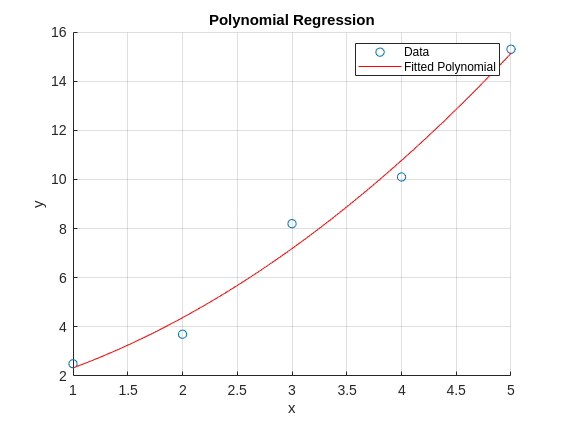


% Plot the original data and the fitted polynomial
figure;
scatter(x, y, 'o', 'DisplayName', 'Data');
hold on;

% Generate points for the fitted polynomial
xFit = linspace(min(x), max(x), 100);
yFit = polyval(flip(coefficients), xFit);  % polyval uses coefficients in descending order

% Plot the fitted polynomial
plot(xFit, yFit, 'r-', 'DisplayName', 'Fitted Polynomial');
legend();
xlabel('x');
ylabel('y');
title('Polynomial Regression');
grid on;
hold off;

# Linear Regression

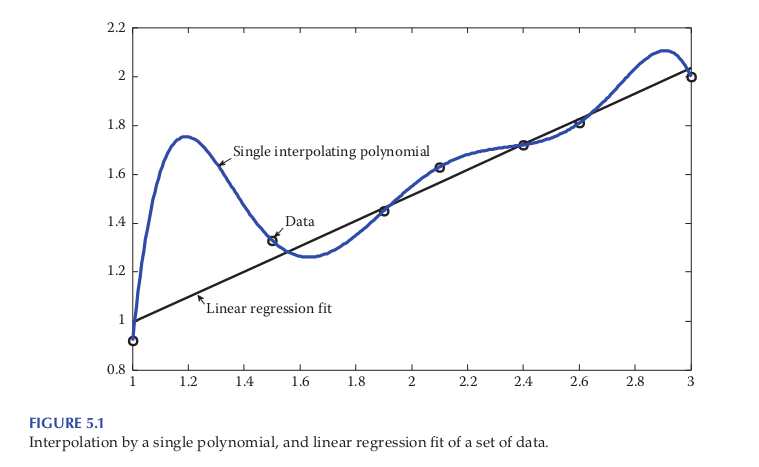

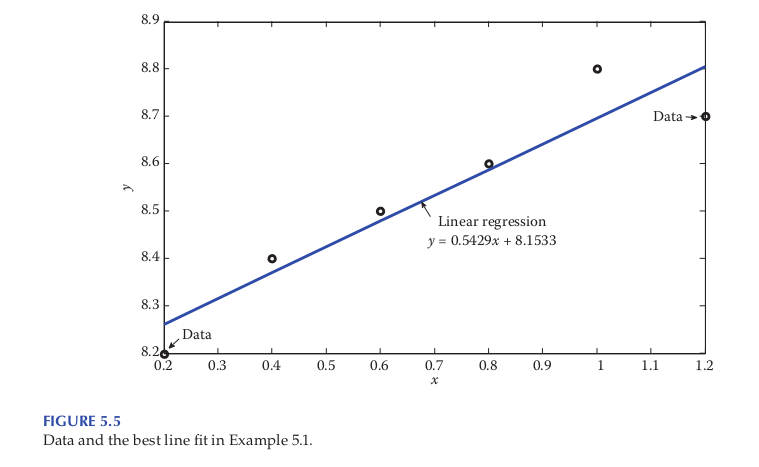

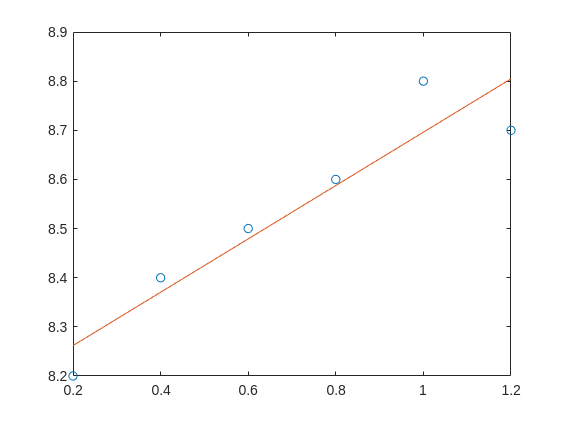

a1 =    0.542857142857136


a0 =    8.153333333333341


clc;clear;clf
x = 0.2:0.2:1.2; y = [8.2 8.4 8.5 8.6 8.8 8.7];
[a1, a0] = LinearRegression(x,y)

# Linearization of Nonlinear Data

- Exponential Function

- Power Function

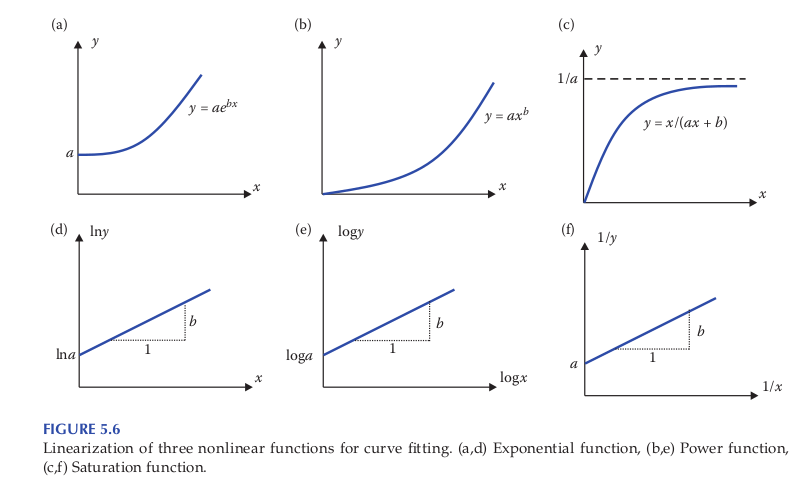

## **Saturation Function**

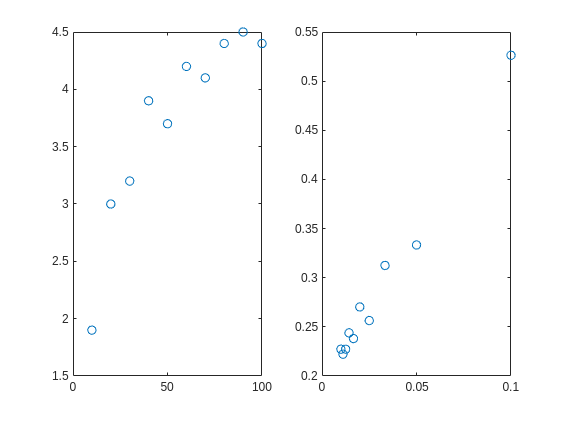

clc;clear;clf
x = 10:10:100; y = [1.9 3.0 3.2 3.9 3.7 4.2 4.1 4.4 4.5 4.4];
xx = 1./x; yy = 1./y;   % Element-by-element reciprocals
subplot(1,2,1), plot(x,y,'o')

subplot(1,2,2), plot(xx,yy,'o')

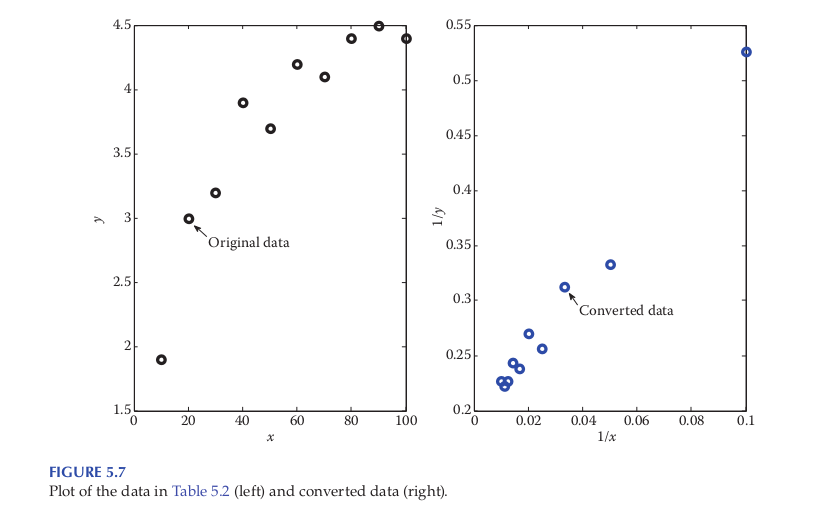

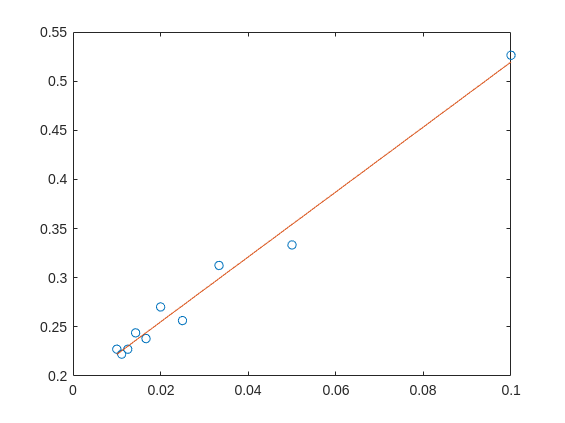

a1 =    3.305168046024646


a0 =    0.188952177529120


clf
[a1, a0] = LinearRegression(xx,yy)

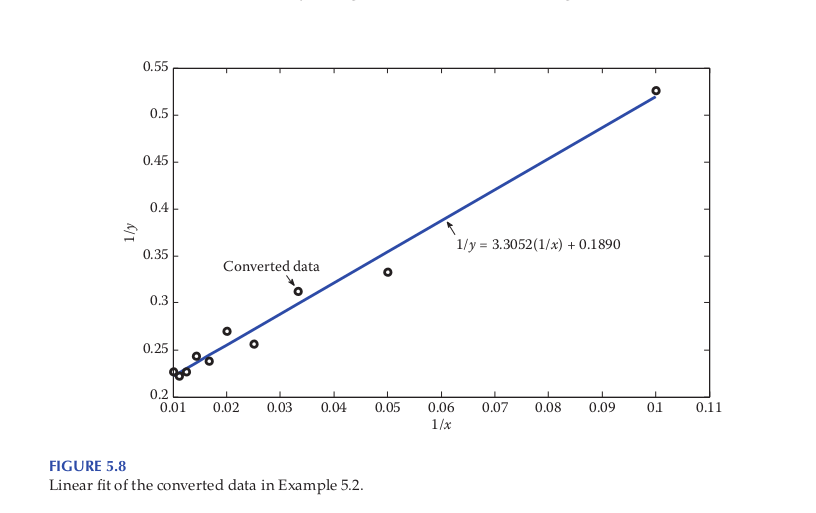

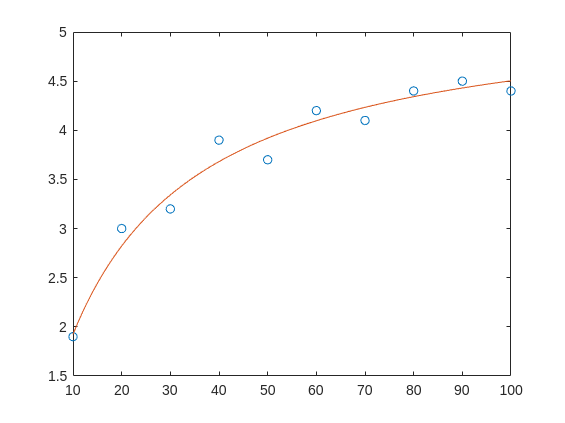

clf;
x_fit = linspace(10,100);
for i = 1:100,
y_fit(i) = x_fit(i)/(0.1890*x_fit(i)+3.3052);%form LinearRegression a0,a1
end
plot(x,y,'o')
hold on
plot(x_fit,y_fit)

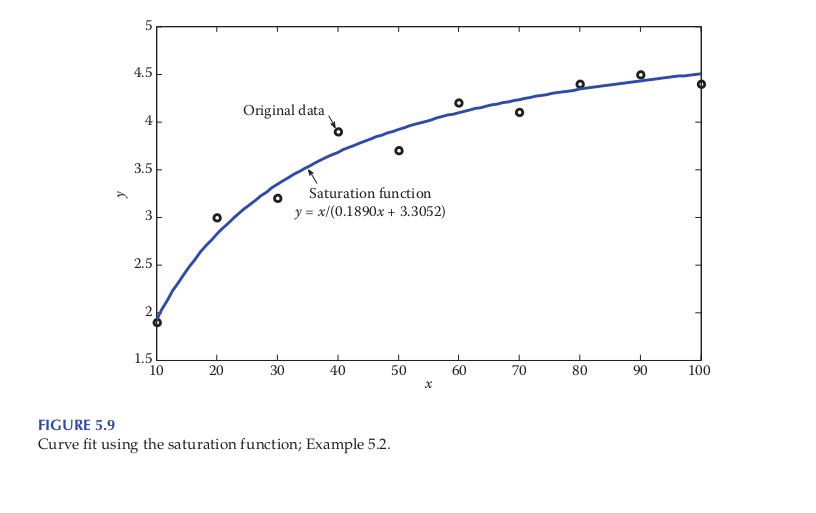

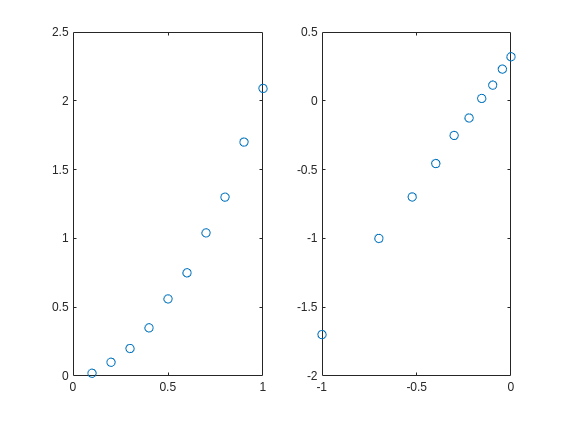

clc;clf;clear;
x = 0.1:0.1:1; y = [0.02 0.1 0.2 0.35 0.56 0.75 1.04 1.3 1.7 2.09];
xx = log10(x); yy = log10(y);
subplot(1,2,1), plot(x,y,'o')
subplot(1,2,2), plot(xx,yy,'o')

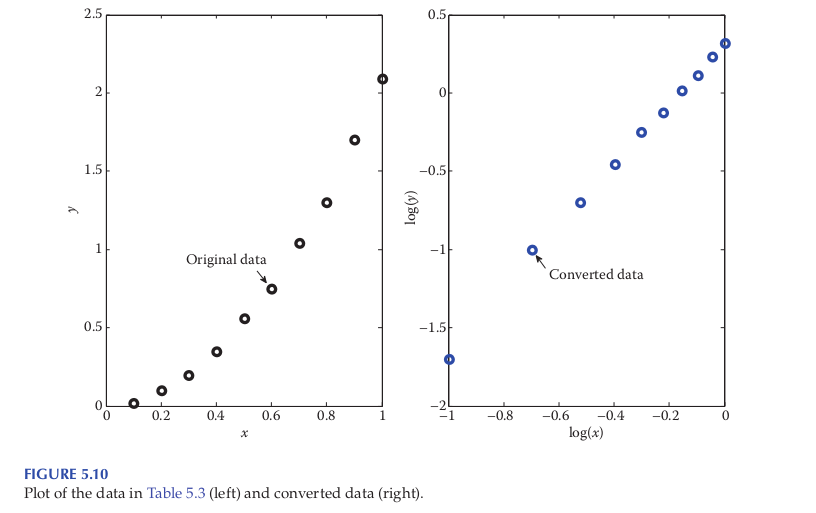

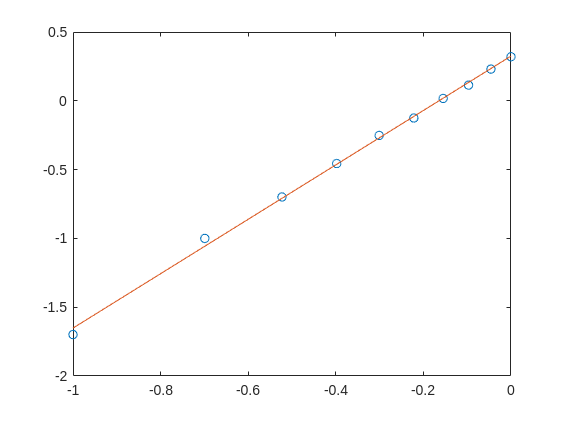

a1 =    1.976940187482075


a0 =    0.325209193993840


clf;
[a1, a0] = LinearRegression(xx,yy)

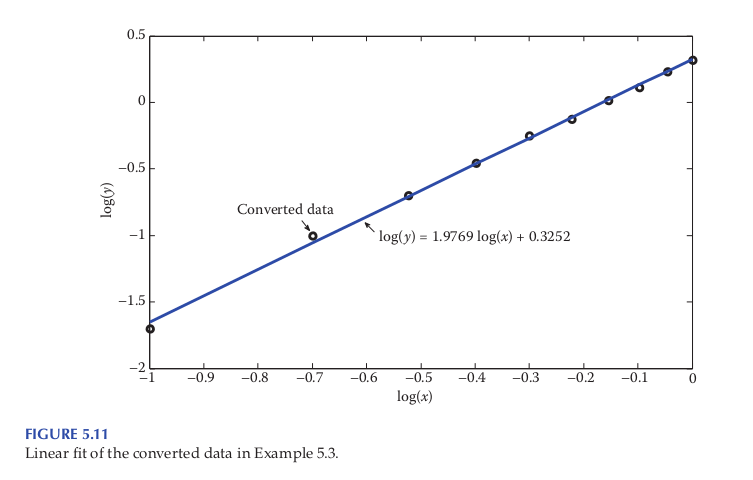

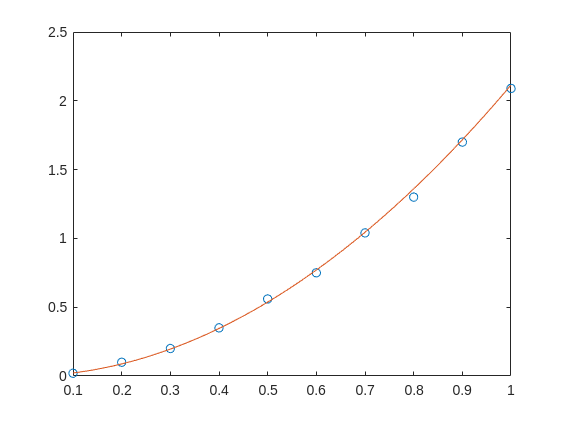

clf;
x_fit = linspace(0.1,1);
%take 10^f(x)
for i = 1:100,
y_fit(i) = 2.1145*x_fit(i)^1.9769; %from LinearRegression 1.9769,log(a)=0.3252 (a=10^.3252=2.1145) so a = 2.1145
end
plot(x,y,'o')
hold on
plot(x_fit,y_fit)

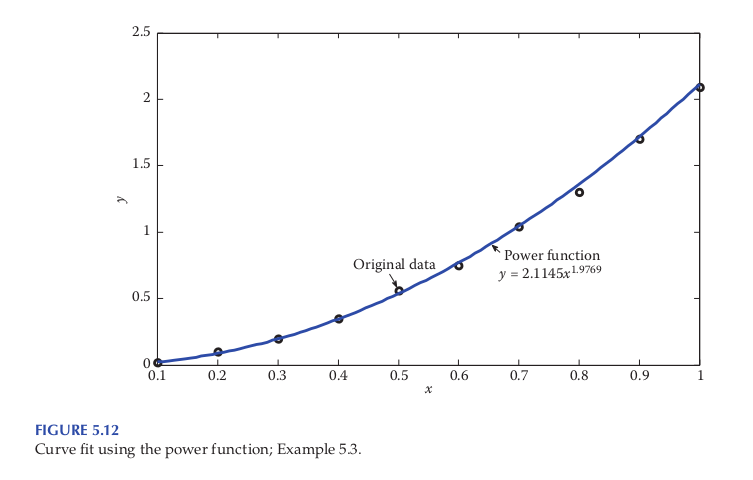

## Polynomial Regression

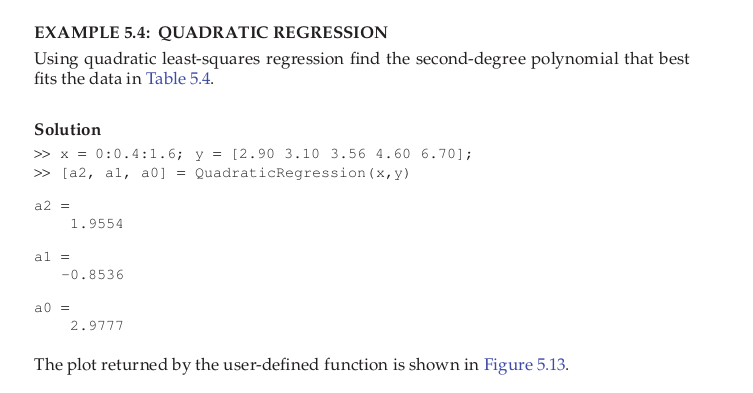

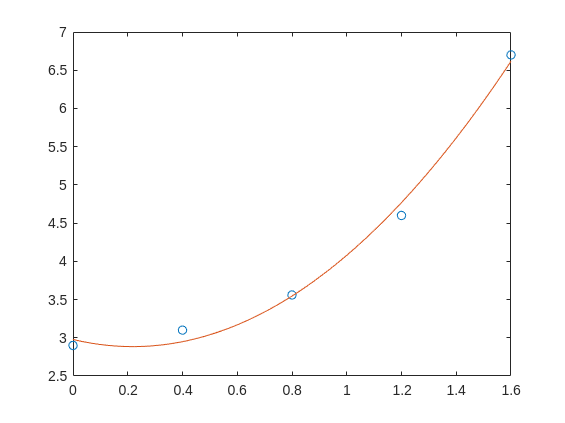

a2 =    1.955357142857143


a1 =   -0.853571428571429


a0 =    2.977714285714285


clc;clf;clear;
x = 0:0.4:1.6; 
y = [2.90 3.10 3.56 4.60 6.70];
[a2, a1, a0] = QuadraticRegression(x,y)

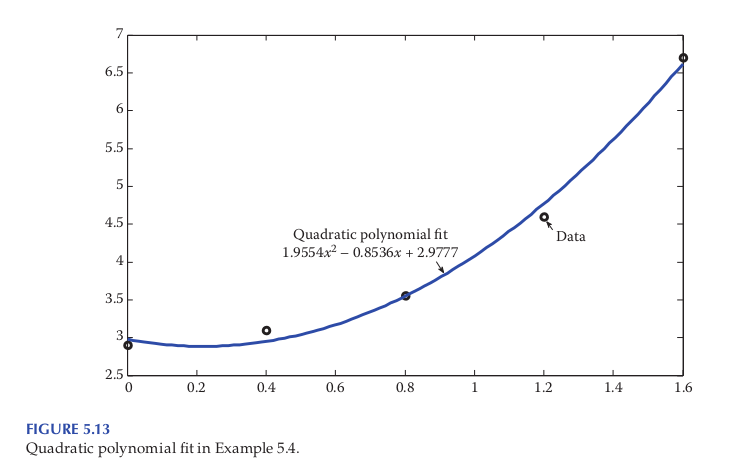

## Built-in Function

- polyfit

- polyval

clf;
x = 0:0.3:1.2; 
y = [3.6 4.8 5.9 7.6 10.9];
P = polyfit(x,y,2)

P =    3.809523809523810   1.228571428571431   3.765714285714284


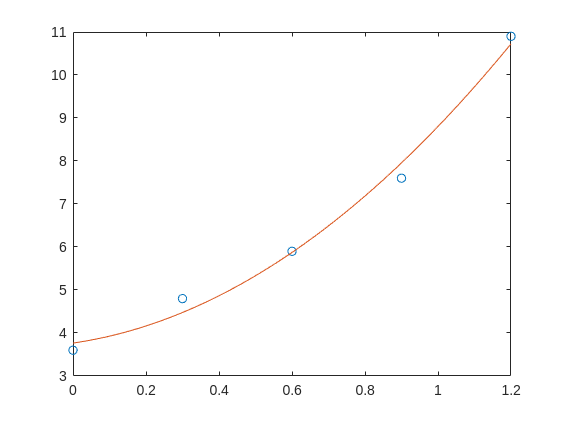

a2 =    3.809523809523823


a1 =    1.228571428571417


a0 =    3.765714285714285



xi = linspace(0,1.2);% Generate 100 points for plotting purposes
yi = polyval(P,xi);% Evaluate the polynomial at these points
plot(xi,yi,x,y,'o')

[a2, a1, a0] = QuadraticRegression(x,y)

%same between built-in function and QuadraticRegression(x,y)

# Polynomial Interpolation

clc;clear;clf
disp("Polynomial Interpolation")

Polynomial Interpolation



% Input the first two data points only
x = [0.1 0.5]; 
y = [1.9048 1.6065];
yi = LagrangeInterp(x,y,0.35)

yi =    1.718362500000000



x = [0.1 0.5 0.8]; 
y = [1.9048 1.6065 1.4493];
yi = LagrangeInterp(x,y,0.35)

yi =    1.706483035714286



x = [0.1 0.5 0.8]; 
y = [1.9048 1.6065 1.4493];

% Specific data to build the first-degree polynomial
x1 = [0.1 0.5]; 
y1 = [1.9048 1.6065];

% 100 points for plotting over the entire (original) data
xi = linspace(0.1,0.8);

% Use the first-degree polynomial [based on (x1,y1)] to evaluate at
% the 100 points
for i = 1:100,
yi(i) = LagrangeInterp(x1,y1,xi(i));
end

% Plot
plot(xi,yi,x,y,'o')
hold on

% Use the second-degree polynomial [based on (x,y)] to evaluate at
% the 100 points
for i = 1:100,
yi(i) = LagrangeInterp(x,y,xi(i));
end

% Complete the figure
plot(xi,yi)

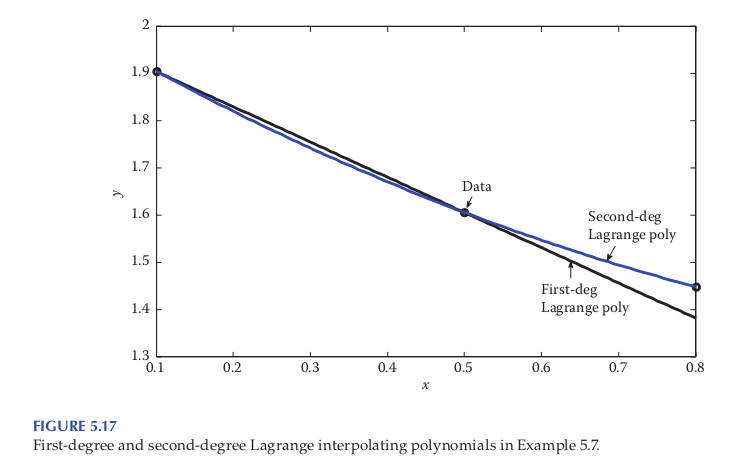

# Newton Divided-Difference Interpolating Polynomials

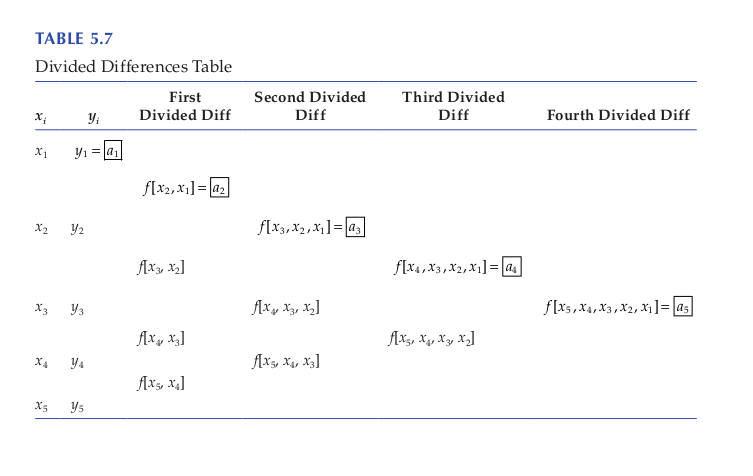

clc;clear;clf
x = [0.1 0.2 0.5]; 
y = [0.1210 0.2258 0.4650];
yi = NewtonInterp(x,y,0.35)% y at x = 0.35

yi =    0.359500000000000


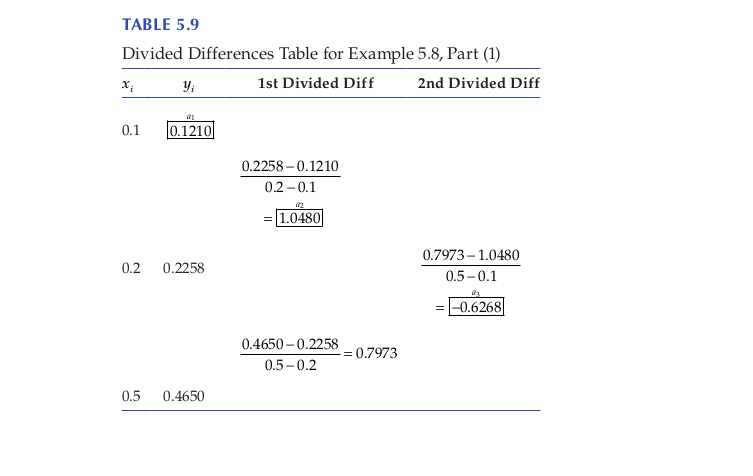

x = [0 0.1 0.2 0.5 0.8]; 
y = [0 0.1210 0.2258 0.4650 0.6249];
yi = NewtonInterp(x,y,0.35)

yi =    0.357685546875000


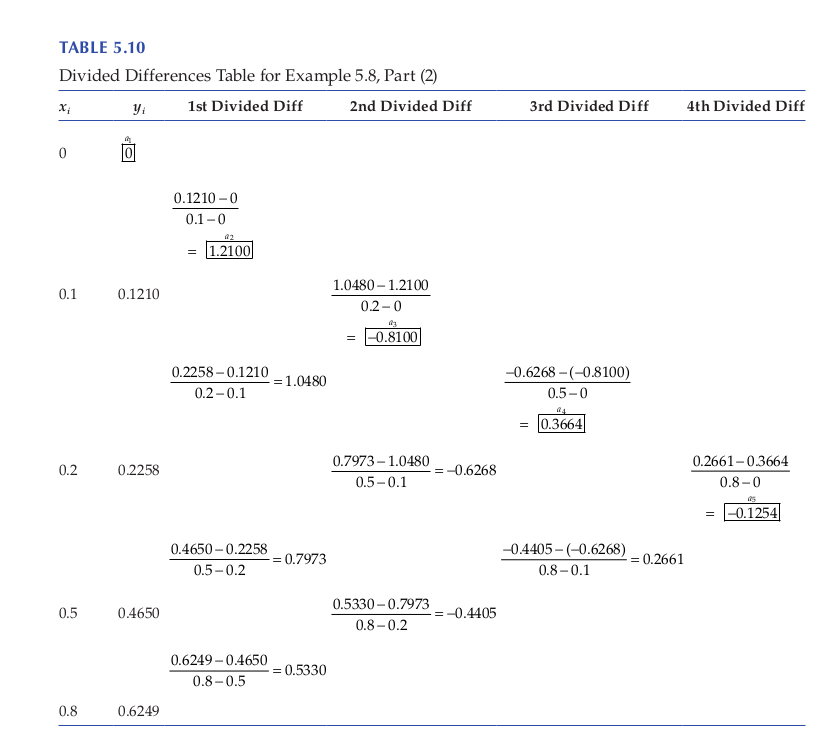

format long
x = [0.4 0.5 0.6 0.7 0.8];
y = [0.921061 0.877583 0.825336 0.764842 0.696707];
yi = NewtonInterp(x,y,0.64)

yi =    0.802095985600000


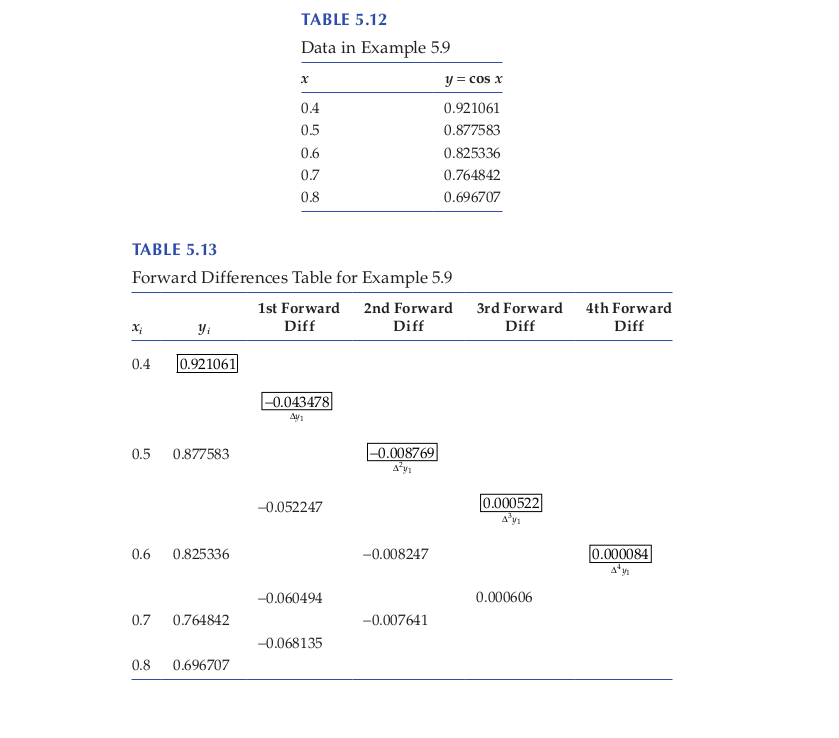

# Built-in Function 

- interp1

- spline

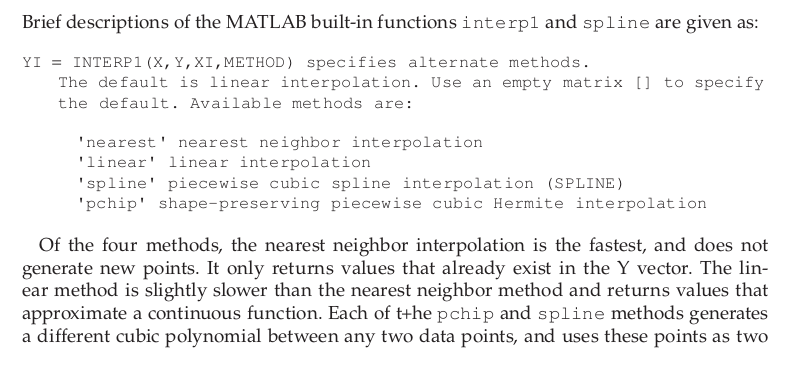

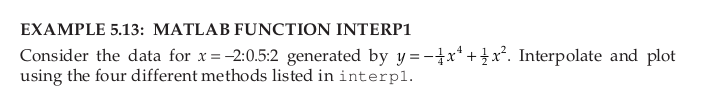

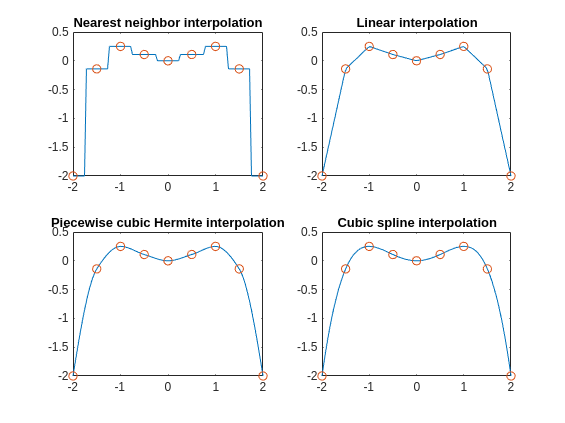

clc;clf;clear;
x = -2:0.5:2;
y = -1./4.*x.^4+1./2.*x.^2;
xi = linspace(-2, 2);
ynear = interp1(x, y, xi, 'nearest');
ylin = interp1(x, y, xi, 'linear');
ypc = interp1(x, y, xi, 'pchip');
yspl = interp1(x, y, xi, 'spline');
% Start Figure 5.24
subplot(2,2,1), plot(xi,ynear,x,y,'o'), title('Nearest neighbor interpolation')
hold on
subplot(2,2,2), plot(xi,ylin,x,y,'o'), title('Linear interpolation')
subplot(2,2,3), plot(xi,ypc,x,y,'o'), title('Piecewise cubic Hermite interpolation')
subplot(2,2,4), plot(xi,yspl,x,y,'o'), title('Cubic spline interpolation')

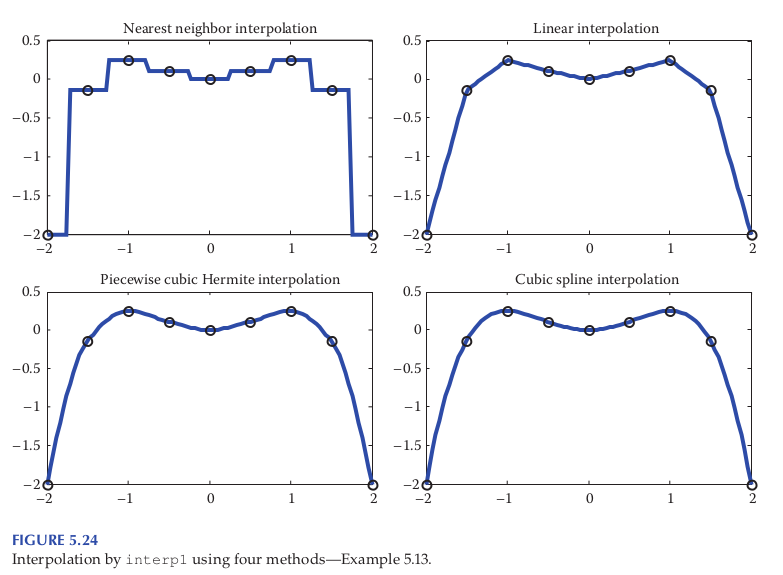

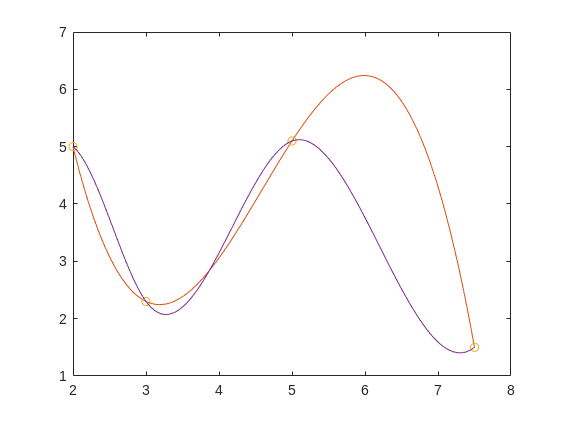

clf;
x = [2 3 5 7.5]; 
y = [5 2.3 5.1 1.5];
xi = linspace(2,7.5);
yi = interp1(x,y,xi,'spline'); % No control over boundary conditions
plot(x,y,'o',xi,yi)
cs = spline(x,[-1 y 1]); % Specify end slopes of -1 and 1
hold on
plot(x,y,'o',xi,ppval(cs,xi),'-');

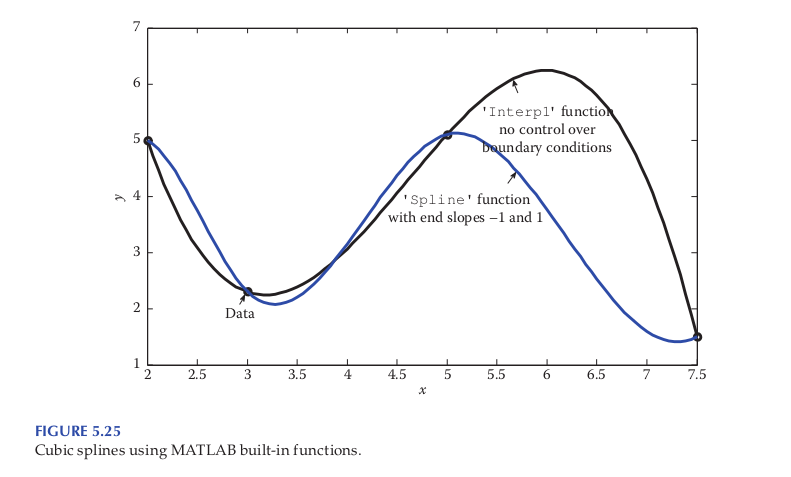

**Interactive Curve Fitting and Interpolation in MATLAB**